clc
clear

% Loading image
image_path = 'CROP1_47.tiff';
hcube = imread(image_path);

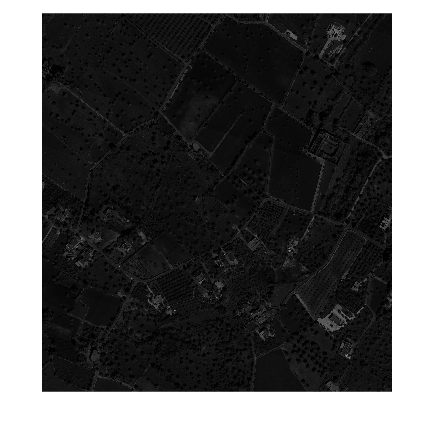

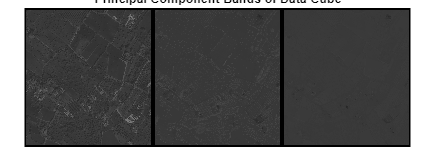

% Calculating PCA
[image,components] = PCA(hcube,5);

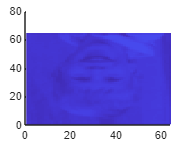

% Reshaping image
pixels = reshape(image, [], size(image, 3));

% DBSCAN clustering
epsilon = 0.5; 
MinPts = 5; 

% Perform DBSCAN clustering
idx = dbscan(pixels, epsilon, MinPts);

% Obtaining image's sizes
[rows, cols, ~] = size(image);


image = reshape(idx, [rows, cols]);

Unrecognized function or variable 'idx'.

% Plot results
figure;

Unrecognized function or variable 'idx'.

imshow(reshape(idx, [rows, cols]), []);
colormap(jet(max(idx)));
colorbar;
title('DBSCAN clustering results');